# Mid-term Progress Test - Fall 2018

## Altitude control of hot air balloon

The problem focuses on the design of a control system that regulates the altitude of a hot air balloon; thus only the vertical degree of freedom of the hot air balloon's movement is of interest here. 

The state variables for the balloon are 

- the altitude, $h$ $[m]$, 

- the vertical velocity, $w$ $[m s^{-1}]$ 

- and the temperature of the heated air in the balloon envelope, $T$ $[K]$. 

The hot air balloon is provided with a gas burner (heat source) that enables the change of altitude by delivering a variable heat quantity, $q$ $[kJ]$. This is the only input to the system. 

The nonlinear state model that describes the vertical motion of the hot air balloon is


$$\dot{T}=-\frac{1}{\tau_1}(T-T_a(h))+cq \\
 M\dot{w}=Vg(\rho_a(h)-\rho)-Mg-bw  \\
 \dot{h}=w \\
y = T$$


where $\tau_1=300 s$, $T_a(h)$ $[K]$ is the ambient temperature of the air surrounding the balloon, $c=1.10^{-3}[K kJ^{-1} s^{-1}]$ is a constant, $\rho_a(h)$ $[kgm^{-3}]$ is the ambient air density, $\rho$$[kgm^{-3}]$ is the density of the air in the balloon envelope, $M=300 kg$ is the total mass of the balloon and its load, $V=2000 m^{3}$ is the volume of the  envelope, $g=9.81 ms^{-2}$is the acceleration  of gravity and $b=6 kg \cdot s^{-1}$ is the air restistance coefficient. The only measured output is the temperature $T$ of the heated air in the balloon envelope.

A hot air balloon rises because by heating the air inside the envelope causes the density of the air to decrease. This decreases the effective weight of the balloon and its load. At the same time as the balloon rises, it moves into air which decreases in temperature and density while at the same time the heat losses increase. Equations (1) and (2) above take these effects into account. What is missing is a description of the relation of the density/temperature product of the envelope air to that of the surrounding air (Boyle's Law) and how the density and temperature vary with altitude. These relationships for this problem are given by:


$$\rho T = \rho_a T_a  \ \  \ \ \ \ \ \ \ \ \ \ \ \  \ \ \ \ \ \ \ \ \ \ \ \   \ \  \  \ \ \  (4)\\
 \rho_a(h) = \rho_a(0)-ph = \rho_a(0)-0.795\cdot 10^{-4}h  \  \   (5)\\
 T_a(h) = T_a(0)-fh = T_a(0) - 6\cdot 10^{-3}h \ \ \ \ \  \ \  (6)$$


where $\rho_a(0)=1.22 [kgm^{-3}]$, $T_a(0)=290K$, $p=0.795 \times 10^{-4}kgm^{-4}$ and $f=6 \times 10^{-3} K m^{-1}$. 

A thermocouple installed inside the balloon envelope provide a measurement of the heated air


$$y=T \qquad (7)$$


The nonlinear model of the hot air balloon (Equations (1)-(7)) is implemented in the Simulink diagram (R2015a) *HotAirBalloon_NonlinearModel.slx*.

clear
% Hot air balloon system parameters
tau1 = 300; % time constant Eq. (1) [sec]
c = 1e-3;   % input gain [K/(kJ*sec)]
M = 300;    % mass [kg]
V = 2000;   % volume [m^3]
g = 9.81;   % gravity constant [m/s^2]
b = 6;      % air resistance coefficient [kg/sec]

rhoa0 = 1.22; % air density [kg/m^3]
Ta0 = 290;    % ambient temperature [K]
p = 0.795e-4; % [kg/m^4]
f = 6e-3;     % [K/m]

**Question 1:** Given the desired operating height $h_s =500m$ determine the steady state operating point $x_{\mathrm{ss}} ={\left\lbrack \begin{array}{c}
T_s  & w_s  & h_s 
\end{array}\right\rbrack }^T$ and $u_{\mathrm{ss}} =q_s$ and verify it numerically.

% Your code goes here
clear
% Hot air balloon system parameters
tau1 = 300; % time constant Eq. (1) [sec]
c = 1e-3;   % input gain [K/(kJ*sec)]
M = 300;    % mass [kg]
V = 2000;   % volume [m^3]
g = 9.81;   % gravity constant [m/s^2]
b = 6;      % air resistance coefficient [kg/sec]

rhoa0 = 1.22; % air density [kg/m^3]
Ta0 = 290;    % ambient temperature [K]
p = 0.795e-4; % [kg/m^4]
f = 6e-3;     % [K/m]

% Symbolic solution
syms stau1 sc sM sV sg sb srhoa0 sTa0 sp sf T w q srho sh
srhoa_h = srhoa0-sp*sh;
sTa_h   = sTa0-sf*sh;
srho = srhoa0*sTa0/T;
sdT = (1/-stau1)*(T-sTa_h)+sc*q;
sdw = (sV*sg*(srhoa_h-srho)-sM*sg-sb*w)/sM;
sdh = w;
sy=T;

sf= [sdT; sdw; sdh]

$$sf = \left(\begin{array}{c} q\,\mathrm{sc}-\frac{T-{\mathrm{sTa}}_{0}+\mathrm{sf}\,\mathrm{sh}}{{\mathrm{stau}}_{1}}\\ -\frac{\mathrm{sM}\,\mathrm{sg}+\mathrm{sb}\,w+\mathrm{sV}\,\mathrm{sg}\,\left(\mathrm{sh}\,\mathrm{sp}-{\mathrm{srhoa}}_{0}+\frac{{\mathrm{sTa}}_{0}\,{\mathrm{srhoa}}_{0}}{T}\right)}{\mathrm{sM}}\\ w \end{array}\right)$$


% Numerical solution
h = 500;                                % Height
rhoa500 = rhoa0-p*h;                    
Ta500   = Ta0-f*h;
rho = rhoa0*Ta0/T;
f1 = (1/-tau1)*(T-Ta500)+c*q;          % f1==0 => dT==0
f2 = (V*g*(rhoa500-rho)-M*g-b*w)/M;     % f2==0 => dw==0
f3 = w;                                 % f3==0 => dh==ws==0
y = T;
func = [f1;f2;f3];
ws = double(solve(f3==0))

ws =      0


sol(w) = solve([f2==0],[T]);
Ts = double(sol(ws))

Ts =        343.41


hs = h;
sol(T) = solve(f1==0,q)

$$sol(T) = \frac{10\,T}{3}-\frac{2870}{3}$$

qs = double(sol(Ts))

qs =        188.04


xss = [Ts ws hs]' %% Stationary-state State vector

xss =        343.41
            0
          500


uss = qs           %% Stationary-state Input Vector

uss =        188.04


**Question 2:** Numerically linearize the nonlinear system around the found operating point. Then graphically evaluate the validity of the linear model with respect to the nonliner model for input step changes of 5%, 10% and 20% of the steady state value $u_{\mathrm{ss}}$.

% Your code goes here
x1 = T; x2 = w; x3 = h; u = q;
x = [x1 x2 x3]';
A = double(subs( [diff(f1,x1) diff(f1,x2) diff(f1,x3);...
           diff(f2,x1) diff(f2,x2) diff(f2,x3);...
           diff(f3,x1) diff(f3,x2) diff(f3,x3)],x1,Ts)) %% Linearizing A

A =    -0.0033333            0            0
       0.1962        -0.02            0
            0            1            0


B = double(subs([diff(f1,u);diff(f2,u);diff(f3,u)],u,qs)) %% Linearizing B

B =         0.001
            0
            0


C = double(subs([diff(y,x1), diff(y,x2), diff(y,x3)],[x1 x2 x3 u], [Ts ws hs qs])) %% Linearizing C

C =      1     0     0


D = double(subs(diff(y,u),[x1 x2 x3 u], [Ts ws hs qs])) %% Linearizing D

D =      0


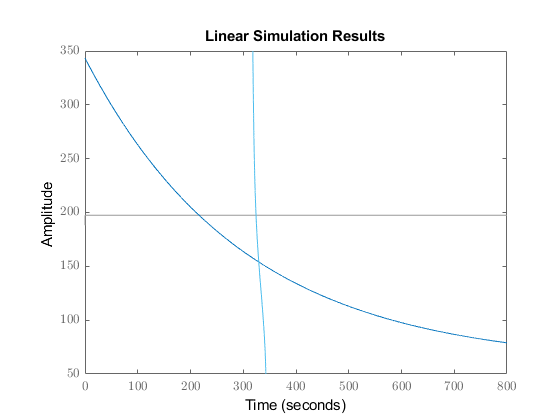

sys_lin = ss(A,B,C,D);
SIM_TIME = 800; STEP_SIZE = 0.1;
x0 = xss;
t = 0:0.1:SIM_TIME;
ut = double(t>0)*0.05*uss+uss;
figure
lsim(sys_lin,ut,t,x0)
sim('HotAirBalloon_NonlinearModel_R2015a_step.slx')
hold on
plot(y_out,t)
 hold off

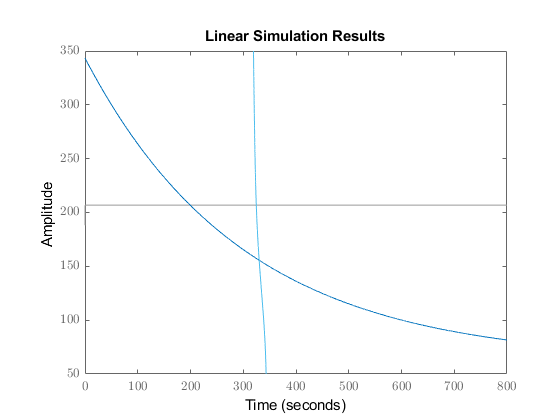

figure
ut = double(t>0)*0.10*uss+uss;
lsim(sys_lin,ut,t,x0)
sim('HotAirBalloon_NonlinearModel_R2015a_step.slx')
hold on
plot(y_out,t)

% 
% figure
% ut = double(t>0)*0.15*uss+uss;
% lsim(sys_lin,ut,t,x0)
% sim('HotAirBalloon_NonlinearModel_R2015a_step.slx')
% hold on
% plot(y_out,t)
% 
% figure
% ut = double(t>0)*0.2*uss+uss;
% lsim(sys_lin,ut,t,x0)
% sim('HotAirBalloon_NonlinearModel_R2015a_step.slx')
% hold on
% plot(y_out,t)
%simOut = sim('HotAirBalloon_NonlinearModel_R2015a.slx');


**Question 3:** Investigate the internal and external stability of the open loop linear model, then conclude on which type of stability the system retains.

% Your code goes here
eigvals = eig(A)

eigvals =             0
        -0.02
   -0.0033333


% Internally the system is stable as all of the eigenvalues are non-positive
[z, p] = ss2zp(A,B,C,D)

z =             0
        -0.02


p =             0
        -0.02
   -0.0033333


% Externally the system is asymptotically stable as the poles at [0, -0.02] 
% cancel with corresponding zeros


**Question 4:** Assess the controllability and observability of the open loop linear model.

% Your code goes here

Mc = ctrb(A,B);
rank(Mc) == size(A,1)

ans = logical
   1


% The open loop system is controllable because the rank of controllability == size of A matrix
Mo = obsv(A,C);
rank(Mo)== size(A,1)

ans = logical
   0


% The open loop system is not observable because the rank of controllability matrix != size of A

**Question 5:** Select a proper sampling time (briefly motivate your choice) and discretize the open loop linear model.

% Your code goes here
timeConsts = -1./eigvals

timeConsts =   -Inf
    50
   300


% The lowest time cosntant from the non-zero internal system poles is 50, 
% so a sample time of 5 seconds is already 10 times faster.
Ts = 5;
sys_lin_d = c2d(sys_lin,Ts);
F = sys_lin_d.A

F =       0.98347            0            0
      0.92569      0.90484            0
       2.3596       4.7581            1


G = sys_lin_d.B

G =     0.0049586
    0.0023596
    0.0039707


C = sys_lin_d.C

C =      1     0     0


D = sys_lin_d.D

D =      0


**Question 6:** Let $e=h_{\mathrm{ref}} -h$be the regulation error, that is the difference between the desired altitude $h_{\mathrm{ref}}$ and the current altitude $h$. Design a discrete time control system such that the closed-loop system fulfils the following requirements

- asymptotic stability

- zero steady state regulation error for step changes in the desired altitude $h_{\mathrm{ref}\text{ }}$

- maximum 5% overshoot for a step change of 10% from the steady state altitude $h_s$

- the 1% settling time between 250 - 300 seconds

% Your code goes here



**Question 7:** Evaluate the performance of the designed control system on the linear and nonlinear open loop system and compare the obtained results. (Expand the given Simulink model by implementing the control system)

% Your code goes here


